## Discretization with real, complex and origin poles, various deltas

[A,B,C,D]=tf2ss(5,[1,5,9,5,0]);
B=[1,0;0,1;0,0;0,1]; %Two control actions
T=2;
Td=T/40;

Continuous simulation:

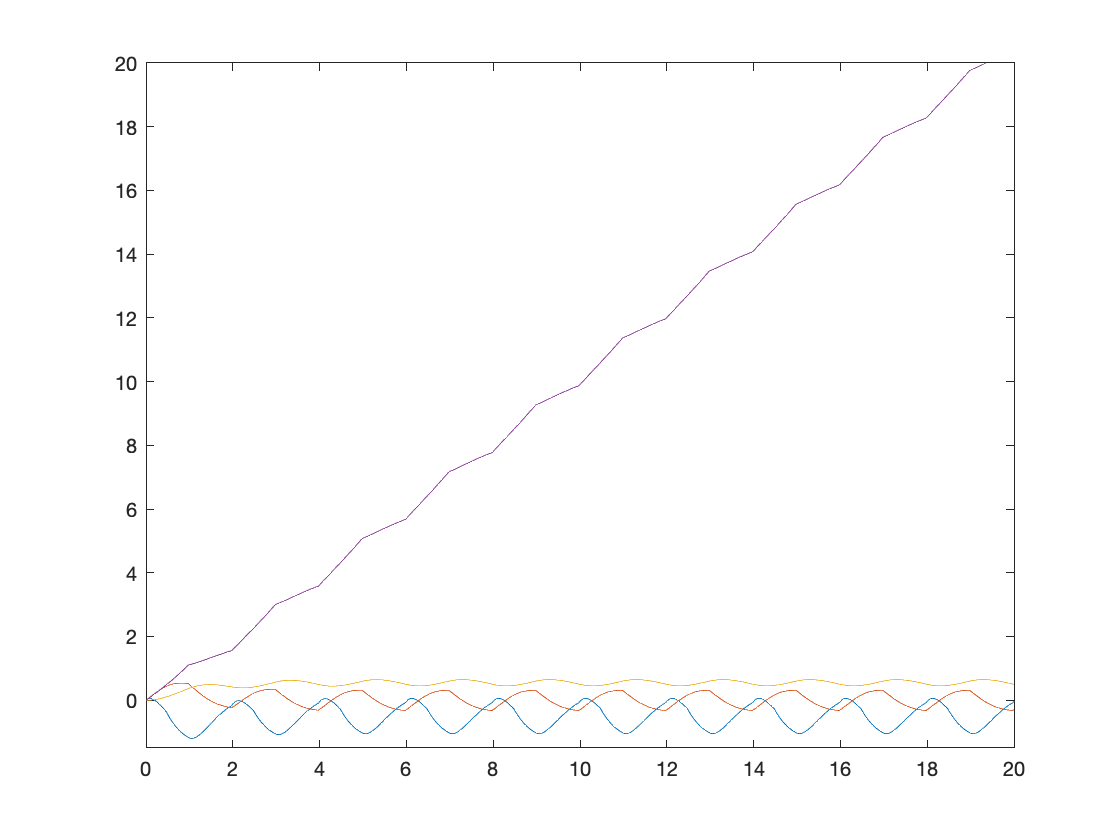

L=length(A);
Td=T/80;
N=50*80;
delta_1=0.25; %Delta 1, First control action
delta_2=0.50; %Delta 2, Second control action
x=zeros(L,N);
x(:,1)=zeros(L,1);
for i=1:N+1
   if (mod(i,80)/80<delta_1)
      x(:,i+1)=x(:,i)+(Td*(A*x(:,i)+B(:,1)+B(:,2))); 
   elseif (mod(i,80)/80<delta_2)
      x(:,i+1)=x(:,i)+(Td*(A*x(:,i)+B(:,2)));
   else
      x(:,i+1)=x(:,i)+ Td*A*x(:,i);
   end
end
figure
t=[0 (1:N+1)*Td];
plot(t,x') 
ylim([-1.5 20])
xlim([0 20])

Discrete simulation, various deltas:

T=2;
tic
[PA,PB,alpha2]=discrete_binary_f(A,B,T); %Same function as other examples.
toc

Elapsed time is 0.028732 seconds.


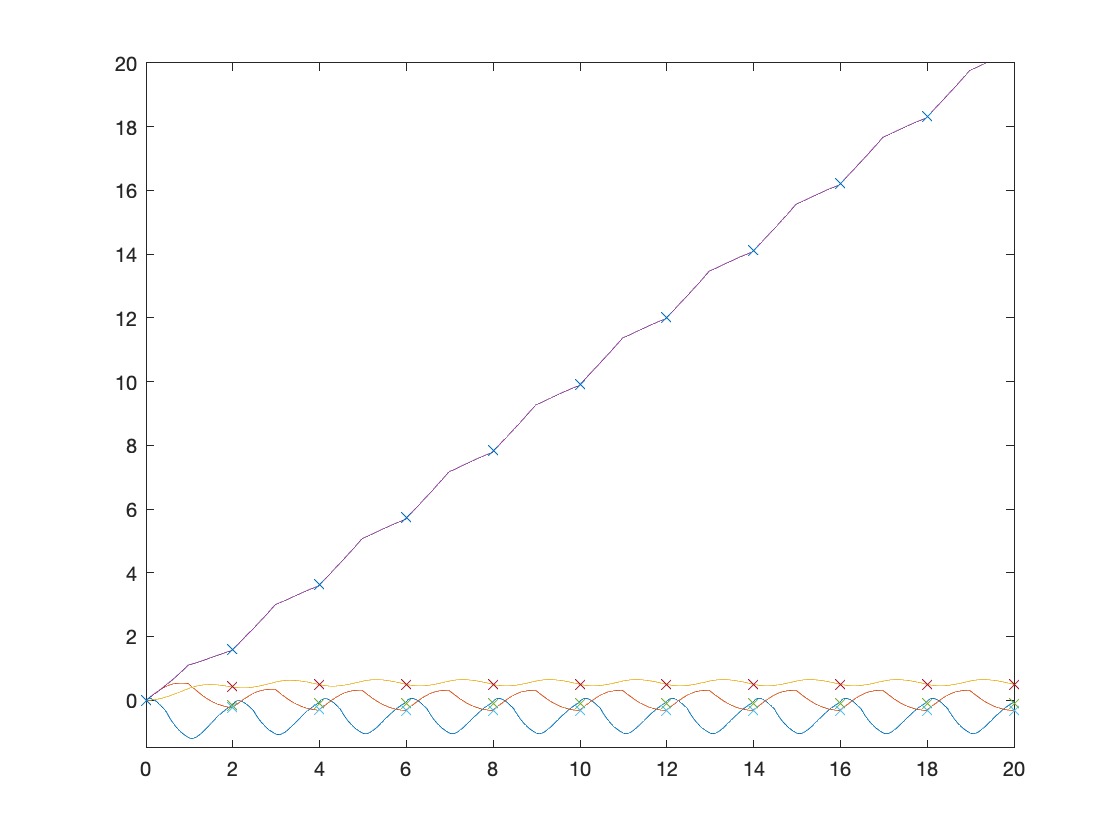

N=50*20;
delta=[0.25 0.5]; %Deltas for both control actions.
x3=zeros(L,N);
x3(:,1)=zeros(L,1);
alpha=[];
r=rank(A);
for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end

for i=1:N+1
    x3(:,i+1)=PA*x3(:,i)+PB.eval(alpha)*delta';
end
figure
plot(t,x);
hold on
t3=[0 (1:N+1)*T];
plot(t3,x3','x')
ylim([-1.5 20])
xlim([0 20])

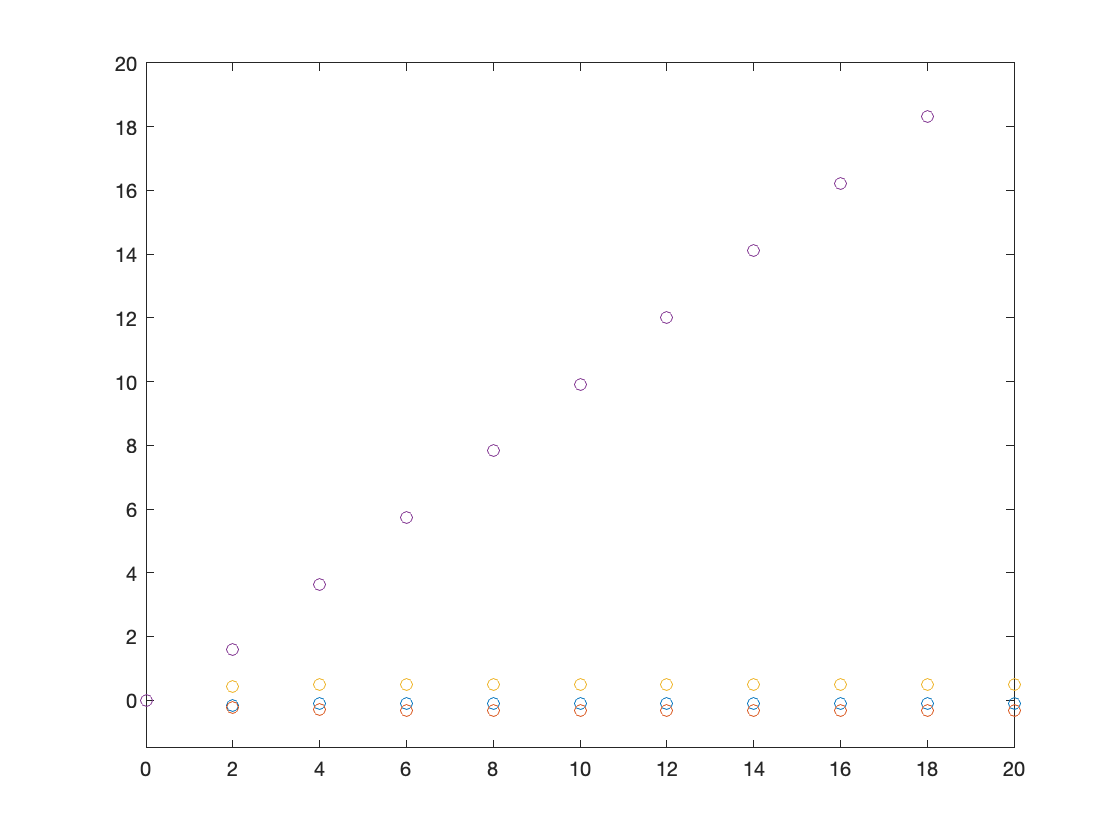

figure
plot(t3,x3','o')
ylim([-1.5 20])
xlim([0 20])